## AST 341 Homework 6 - Simon Xia

### Promlem 1

*Polytropes.* One result for polytropes we used in class is a relation between the central pressure, $P_c$, and central density, $\rho _c$:


$$P_c=(4\pi)^{1/3}B_nGM^{2/3}\rho_c^{4/3}$$


where only $B_n$ depends on the polytopic index $n$ (this is Eq. 5.28 in your text). Here we derive this result. Starting with the equation for mass we had in class:


$$M_\star=\frac1{\sqrt{4\pi}}\left(\frac{n+1}G\right)^{3/2}K^{3/2}\rho_c^{(3-n)/2n}M_n$$


where


$$M_n=-\xi_1^2\left.\frac{d\theta}{d\xi}\right|_{\xi_1}$$


solve for $K$ and then insert your expression for $K$ into our polytropic EOS:


$$P_c=K\rho_c^{1+1/n}$$


and rearrange to find $B_n$ in terms of $n$.

Evaluate your expression for $B_n$ at $n = 1,2,3,4$.

# Solution

Following the instructions, we first solve for $K$ in the equation of mass:

syms pi n G K rho_c M_n M_star B_n positive
K=solve(M_star==1/sqrt(4*pi)*((n+1)/G)^(3/2)*K^(3/2)*rho_c^((3-n)/(2*n))*M_n,K);
K=simplify(K)

$$K = \frac{2^{2/3}\,G\,{M_{\mathrm{star}}}^{2/3}\,\pi^{1/3}\,{\rho_{c}}^{\frac{n-3}{3\,n}}}{{M_{n}}^{2/3}\,\left(n+1\right)}$$

Then insert the expression for $K$ into polytropic EOS:

P_c=K*rho_c^(1+1/n);
P_c=simplify(P_c)

$$P\_c = \frac{2^{2/3}\,G\,{M_{\mathrm{star}}}^{2/3}\,\pi^{1/3}\,{\rho_{c}}^{4/3}}{{M_{n}}^{2/3}\,\left(n+1\right)}$$

This equals to $(4\pi)^{1/3}B_nGM^{2/3}\rho_c^{4/3}$, so we can solve for $B_n$:

B_n=solve(P_c==(4*pi)^(1/3)*B_n*G*M_star^(2/3)*rho_c^(4/3),B_n);
B_n=simplify(B_n)

$$B\_n = \frac{1}{{M_{n}}^{2/3}\,\left(n+1\right)}$$

Now, we can put in $n=1,2,3,4$ to calculate $B_n$ (using value of $M_n$ from lecture slides)

M_1=3.14159;M_2=2.41105;M_3=2.01824;M_4=1.79723; % On page 21 of "stellar-models.pdf" poseted on brightspace
subs(B_n,{n,M_n},{[1;2;3;4],[M_1;M_2;M_3;M_4]});
disp(table([1;2;3;4],vpa(ans),'VariableNames',{'n','B_n'}));

    n      B_n  
    _    _______

    1    0.2331 
    2    0.18539
    3    0.15654
    4    0.1353 



### Problem 2

*Ignition curves.* In chapter 7 we derived an approximate expression for ignition curves in the $\log_{10} \rho$-$\log_{10} T$ plane. We’ll follow your text, and define ignition to be when $q = q_\rm{min}$, with $q_{\rm{min}} \sim  10^3 ~\rm{erg~ g^{-1}~ s^{-1}}$.

Your goal is to make a plot with the H and He ignition curves on the same plot.

$\bullet$ For H, take the the energy generation as


$$q_{pp}=\frac{2.4\times10^4\rho X^2}{T_9^{2/3}}e^{-3.380/T_9^{1/3}}\mathrm{~erg~g}^{-1}\mathrm{~s}^{-1}$$


and


$$q_{\mathrm{CNO}}=\frac{4.4\times10^{25}\rho\mathrm{XZ}}{T_9^{2/3}}e^{-15.228/T_9^{1/3}}\mathrm{~erg~g}^{-1}\mathrm{~s}^{-1}$$


Here, $T_9 \equiv  T/(10^9~\rm K)$. Since both processes are taking place, we can plot the curve:


$$q_{\mathrm{pp}}+q_{\mathrm{CNO}}=q_{\mathrm{min}}$$


This gives us a set of points $(T,\rho )$ in the plot. Take the composition to be solar.

*Hint:* you should be able to solve this expression for $\rho (T)$ and then plot that.

Note: you should only use a temperature range for which the resulting density is something you might expect to encounter inside of a star. So restrict the temperatures you use such that the density is $1\text{ g cm}^{-3}≲~\rho≲~10^4\text{ g cm}^{-3}$.

$\bullet$ For He, use:


$$q_{3\alpha}=5.09\times10^{11}\rho^2Y^3T_8^{-3}e^{-44.027/T_8}\mathrm{~erg~g^{-1}~s^{-1}}$$


Here, $T_8 \equiv  T/(10^8\rm ~K)$ and $Y$ is the mass fraction of helium. Again, you should restrict the temperature range to give reasonable densities, but now since the star will have contracted as it approaches He ignition, you can extend the upper range of density to $\sim10^6 ~\rm{g~ cm}^{-3}$. You can take $Y \sim  1$now, since He burning begins once all of the H is exhausted ($X \sim  0$).

$\bullet$ Put a point in your plot indicating where the Sun’s core is.

# Solution

#### 1. Derive the $\rho$-$T$ relationship for Hydrogen fusion

According to [NASA](https://solarsystem.nasa.gov/genesismission/gm2/science/sunlight_solar-heat/fusion_chemistry.htm#:~:text=The%20composition%20of%20the%20sun,and%200.1%25%20other%20heavier%20elements.), the solar composition is: $X\sim 71\%$, $Y\sim 27\%$ and $Z\sim2\%$. So the energy generation rate becomes

syms T_9 rho positive
X=0.71;Z=0.02;
u=symunit();
q_pp=(2.4e4*rho*X^2/T_9^(2/3))*exp(-3.380/T_9^(1/3))*u.erg/u.g/u.s;
q_CNO=(4.4e25*rho*X*Z/T_9^(2/3))*exp(-15.228/T_9^(1/3))*u.erg/u.g/u.s;
disp("q_pp"==vpa(q_pp));disp("q_CNO"==vpa(q_CNO))

$$q_{\mathrm{pp}}=\frac{12098.0\,\rho \,{\mathrm{e}}^{-\frac{3.38}{{T_{9}}^{1/3}}}}{{T_{9}}^{2/3}}\,\frac{\mathrm{erg}}{g\,s}$$

$$q_{\mathrm{CNO}}=\frac{6.248e+23\,\rho \,{\mathrm{e}}^{-\frac{15.228}{{T_{9}}^{1/3}}}}{{T_{9}}^{2/3}}\,\frac{\mathrm{erg}}{g\,s}$$

Since $q_{\mathrm{pp}}+q_{\mathrm{CNO}}=q_{\mathrm{min}}$

q_min=q_CNO+q_pp;
disp("q_min"==vpa(q_min));

$$q_{\min}=\frac{12098.0\,\rho \,{\mathrm{e}}^{-\frac{3.38}{{T_{9}}^{1/3}}}}{{T_{9}}^{2/3}}\,\frac{\mathrm{erg}}{g\,s}+\frac{6.248e+23\,\rho \,{\mathrm{e}}^{-\frac{15.228}{{T_{9}}^{1/3}}}}{{T_{9}}^{2/3}}\,\frac{\mathrm{erg}}{g\,s}$$

Take $q_{\rm{min}} =  10^3 ~\rm{erg~ g^{-1}~ s^{-1}}$ and solve for $\rho (T)$:

rho_H=solve(1000*u.erg/u.g/u.s==q_min,rho);
rho_H=vpa(simplify(rho_H))

$$rho\_H = \frac{156250.0\,{T_{9}}^{2/3}\,{\mathrm{e}}^{\frac{15.228}{{T_{9}}^{1/3}}}}{1.8904e+6\,{\mathrm{e}}^{\frac{11.848}{{T_{9}}^{1/3}}}+9.7625e+25}$$

#### 2. Derive the $\rho$-$T$ relationship for Helium fusion

Put in $Y = 1$ to the 3$\alpha$ equation:

syms T_8 positive
Y=1;
q_3a=5.09e11*rho^2*Y^3*T_8^(-3)*exp(-44.027/T_8)*u.erg/u.g/u.s;
disp("q_3a"==vpa(q_3a));

$$q_{\mathrm{3a}}=\frac{5.09e+11\,\rho^{2}\,{\mathrm{e}}^{-\frac{44.027}{T_{8}}}}{{T_{8}}^{3}}\,\frac{\mathrm{erg}}{g\,s}$$

Let $q_{3\alpha}=q_{\rm{min}} =  10^3 ~\rm{erg~ g^{-1}~ s^{-1}}$ and solve for $\rho (T)$:

rho_He=solve(1000*u.erg/u.g/u.s==q_3a,rho);
rho_He=vpa(simplify(rho_He))

$$rho\_He = 0.000044324\,{T_{8}}^{3/2}\,{\mathrm{e}}^{22.014/T_{8}}$$

#### 3. Plot in the $\log_{10} \rho$-$\log_{10} T$ plane

In homework 3, we drew the $\log_{10} \rho$-$\log_{10} T$ plane which shows stars dominate by different pressures:

% This block of code is from my Homework 3 Problem 3 solution, here I 
% only modified some plotting configurations
import const.*
syms P_rad P_gas P_e P_e_r a T k_B mu m_H K_1 K_2 mu_e positive
pi=3.14159;
P_rad=a*T^4/3;
P_gas=rho*k_B*T/mu/m_H;
T1=solve(P_gas==P_rad,T);
T1=simplify(subs(T1,[k_B a m_H rho],[const.k_B 8*pi^5*const.k_B^4/const.c^3/15/const.h^3 const.m_H u.g/u.cm^3*rho]));
P_e=K_1*(rho/mu_e)^(5/3);
T2=simplify(solve(P_gas==P_e,T));
T2=simplify(subs(T2,[k_B K_1 m_H rho],[const.k_B 1e7*u.m^4*u.kg^(-2/3)/u.s^2 const.m_H u.g/u.cm^3*rho]));
P_e_r=K_2*(rho/mu_e)^(4/3);
T3=simplify(solve(P_gas==P_e_r,T));
T3=simplify(subs(T3,[k_B K_2 m_H rho],[const.k_B 1.24e10*u.m^3*u.kg^(-1/3)/u.s^2 const.m_H u.g/u.cm^3*rho]));
rho1=solve(P_e==P_e_r,rho);
rho1=vpa(subs(rho1,[K_1 K_2],[1e7*u.m^4*u.kg^(-2/3)/u.s^2 1.24e10*u.m^3*u.kg^(-1/3)/u.s^2]));
rho1=unitConvert(rho1,"CGS");
T1=separateUnits(subs(T1,[mu mu_e],[0.61 2]));
T2=separateUnits(subs(T2,[mu mu_e],[0.61 2]));
T3=separateUnits(subs(T3,[mu mu_e],[0.61 2]));
rho1=double(separateUnits(subs(rho1,[mu mu_e],[0.61 2])));
p1=area([0.1 subs(solve(T1==T,rho),T,1e10)],[1e10 1e10],'LineStyle','none','FaceColor','#B2DFEE');
hold on
p2=area([0.1 subs(solve(T1==T,rho),T,1e10) 1e10],[subs(T1,rho,0.1) 1e10 1e10],'LineStyle','none','FaceColor','#E0E0E0');
p3=area([10 rho1 rho1],[1e5 subs(T2,rho,rho1) 1e5],'LineStyle','none','FaceColor','#EED5D2');
p4=area([rho1 1e10],[subs(T2,rho,rho1) subs(T3,rho,1e10)],'LineStyle','none','FaceColor','#CD9B9B');
fplot(T1,"LineWidth",1.5,"LineStyle","--","Color","b")
fplot(T2,[0.1 rho1],"LineWidth",1.5,"LineStyle","--","Color","b")
fplot(T3,[rho1 1e10],"LineWidth",1.5,"LineStyle","--","Color","b")
plot([rho1 rho1],[1e5 subs(T2,rho,rho1)],"LineWidth",1.5,"LineStyle","--","Color","b")
set(gca(),'XScale','log','YScale','log')
xlim([0.1 1e10]);ylim([1e5 1e10]);
set(gca(),"FontSize",15,"LineWidth",1,'fontname','CMU Serif')
xlabel("$\rho \ \rm [g/cm^3]$");ylabel("$T \ \rm[K]$");
view(90,-90)
yticks([1e5 1e6 1e7 1e8 1e9 1e10])
xticks([1 1e2 1e4 1e6 1e8 1e10])

We can numerically solve the temperature range:

% For H, solve for T_9 that satisfies 1<rho<1e4
T_H1=vpasolve(rho_H==1,T_9,[0 1]);
T_H2=vpasolve(rho_H==1e4,T_9,[0 0.1]);
disp('T Range of H:');disp([T_H2 T_H1])

T Range of H:


$$\left(\begin{array}{cc} 0.012305 & 0.027789 \end{array}\right)$$

% For He, solve for T_8 that satisfies 1<rho<1e6
T_He1=vpasolve(rho_He==1,T_8,[0 3]);
T_He2=vpasolve(rho_He==1e6,T_8,[0 3]);
disp('T Range of He:');disp([T_He2 T_He1])

T Range of He:


$$\left(\begin{array}{cc} 0.91849 & 2.5546 \end{array}\right)$$

Now, plot $\rho_H (T)$ and $\rho_{He} (T)$:

x1=linspace(T_H1,T_H2,1000);
y1=subs(rho_H,T_9,x1);
plot(y1,x1.*1e9,'.','Color','k')
x2=linspace(T_He1,T_He2,1000);
y2=subs(rho_He,T_8,x2);
plot(y2,x2.*1e8,'.','Color','k')
text(10,1.05e6,"H Ignition $\rightarrow$","FontSize",14,"Color","k")
text(0.5e2,2e8,"$\leftarrow$He Ignition","FontSize",14,"Color","k")

#### 4. Plot our Sun

By the polytrope model EOS and ideal gas equation, the $\rho_c$-$T_c$ relation of a main sequence star dominated by ideal gas pressure can be described as ([eq 7.12](https://icourse.club/uploads/files/fa6ee05bde8e18abf27d7e7e444eb7a5e5c47bc7.pdf#page=154) from textbook):


$$\rho_c=\frac{K_0^3}{4\pi B_n^3G^3}\frac{T_c^3}{M^2}$$


where $K_0=k_B/m_H\mu$. For the solar composition, $\mu=0.61$;

and $B_n$ is the polytrope constant determined by $n$. For a main sequence star like our Sun, take $n=3$ so $B_n=0.1565$ (which is calculated in Problem 1). We put in values

syms T_c
rho_c=(const.k_B/0.61/const.m_H)^3/(4*pi*0.1565^3*const.G^3)*T_c^3/const.M_sun^2;
rho_c=unitConvert(rho_c,"CGS")

$$rho\_c = 4.4692e-20\,{T_{c}}^{3}\,\frac{g}{K^{3}\,{\mathrm{cm}}^{3}}$$

Then we can plot the evolution line for the $1M_\odot$ main sequence star (i.e., the Sun). 

x3=linspace(1e5,3e8,1000);
y3=double(subs(separateUnits(rho_c),T_c,x3));
plot(y3,x3,"LineWidth",1.5,"LineStyle",":","Color","r");

Currently, our sun is burning Hydrogen fule, so the core's temperature and density can be approximated by finding its intersection with the Hydrogen ignition curve:

T_c_approx=1.93e7*u.K; % This is roughly approximated by observing
rho_c_approx=subs(rho_c,T_c,T_c_approx);
p5=plot(separateUnits(rho_c_approx),separateUnits(T_c_approx),".","MarkerSize",18,"Color","r");
text(1e5,1.6e8,"$\leftarrow$1M$_{\odot}$ MS star","FontSize",14,"Color","r")
disp('rho_c_approx'==rho_c_approx);disp('T_c_approx'==T_c_approx);

$$\rho_{c,\mathrm{approx}}=321.29\,\frac{g}{{\mathrm{cm}}^{3}}$$

$$T_{c,\mathrm{approx}}=19300000\,K$$

Those approximated values are close to true values found on [nasa](https://nssdc.gsfc.nasa.gov/planetary/factsheet/sunfact.html): $\rho_{c}=162~\rm{g/cm^3}$, $T_{c}=1.57\times 10^7~\rm{K}$, just a slightly larger.

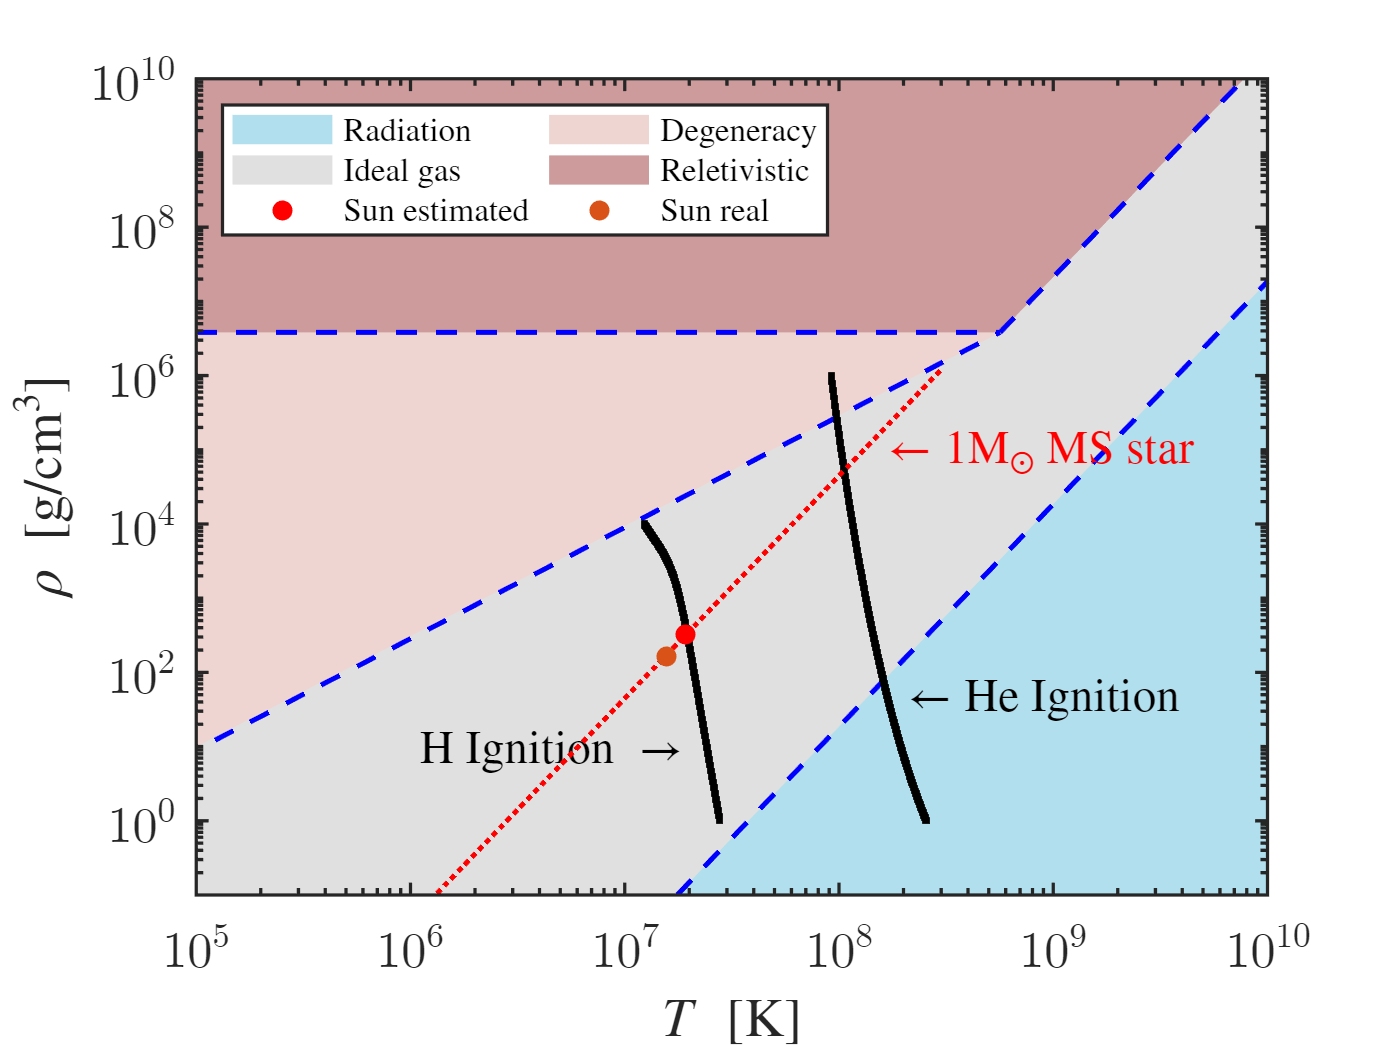

% Plot the true value
p6=plot(162,1.57e7,".","MarkerSize",18,"Color","#D95319");
lgd=legend([p1,p2,p5,p3,p4,p6],{'Radiation','Ideal gas','Sun estimated','Degeneracy','Reletivistic','Sun real'},'Location','northwest','FontSize',10,'Interpreter','latex');
lgd.NumColumns = 2;